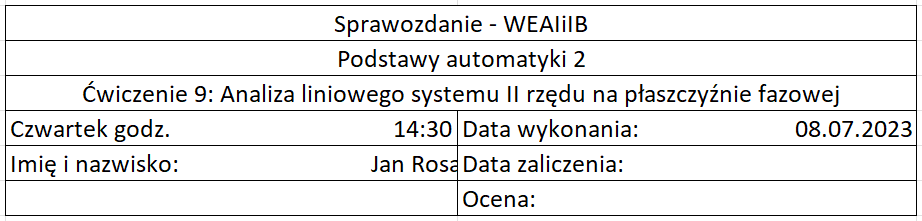

## Wstęp

Ćwiczenie dotyczy analizy liniowego systemu drugiego rzędu na płaszczyźnie fazowej przy wykorzystaniu metody płaszczyzny fazowej. Jest to narzędzie wygodne i efektywne w analizie własności tak liniowych, jak i nieliniowych systemów dynamicznych opisanych w przestrzeni stanu. Metoda płaszczyzny fazowej umożliwia wizualizację i zrozumienie zachowania systemu, takich jak stabilność, oscylacje, tłumienie, a także identyfikację charakterystycznych punktów równowagi.

W celu przeprowadzenia ćwiczenia wykorzystamy narzędzie SIMULINK, które pozwoli nam na budowę modelu simulinkowego traj_fazowe. Ten model będzie reprezentował nasz system dynamiczny w postaci równań stanu (State-Space). Aby przeprowadzić analizę, skonfigurujemy model według podanych w instrukcji parametrów.

Następnie, przygotujemy skrypt, który pozwoli nam automatycznie generować zestawy trajektorii fazowych dla różnych systemów dynamicznych drugiego rzędu. Skrypt ten będzie wywoływał model simulinkowy traj_fazowe dla różnych warunków początkowych i będzie rysował trajektorie fazowe w przestrzeni fazowej. Dzięki temu będziemy mogli obserwować zachowanie systemu w czasie oraz analizować jego stabilność i inne charakterystyczne właściwości.

W ramach ćwiczenia będziemy badać zestawy trajektorii fazowych dla różnych macierzy stanu opisujących systemy dynamiczne drugiego rzędu. Te macierze stanu będą reprezentować różne typy systemów, takie jak stabilny aperiodyczny, stabilny oscylacyjny tłumiony, oscylacyjny nie tłumiony, z całkowaniem oraz niestabilne systemy. Analiza tych zestawów trajektorii fazowych pozwoli nam na wnioskowanie na temat stabilności, oscylacji, tłumienia oraz innych charakterystycznych właściwości tych systemów.

%skrypt do generowania trajektorii fazowych:
%Nazwa do wywołania: tr_faz
%Tu wpisujemy macierz stanu:
Av ={[-1, 0; 0, -2];
    [0, 1; -3, -2];
    [-1, 0; 0, -2];
    [0, 0; 0, -1];
    [0, 2; 0, -1];
    [0.5, 0; 0, -0.5];
    [0, 0.1; 0.2, 0];
    [0, 0; 0, 1];
    };

opis = [
"układ stabilny aperiodyczny, dwie różne rzeczywiste wartości własne,"
"układ stabilny oscylacyjny tłumiony, para wartości własnych zespolonych sprzężonych,"
"układ oscylacyjny nie tłumiony (granica stabilności), jedna para wartości własnych czysto urojonych,"
"układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero,"
"układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero,"
"układ niestabilny, jedna wartość własna dodatnia, druga ujemna (punkt równowagi to punkt „siodłowy”),"
"układ niestabilny, jedna wartość własna dodatnia, druga ujemna (punkt równowagi to punkt „siodłowy”),"
"układ niestabilny, jedna wartość własna rzeczywista, druga równa zero,"
];

opis = 8×1 string array
    "układ stabilny aperiodyczny, dwie różne rzeczywiste wartości własne,"
    "układ stabilny oscylacyjny tłumiony, para wartości własnych zespolonych sprzężonych,"
    "układ oscylacyjny nie tłumiony (granica stabilności), jedna para wartości własnych czysto urojonych,"
    "układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero,"
    "układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero,"
    "układ niestabilny, jedna wartość własna dodatnia, druga ujemna (punkt równowagi to punkt „siodłowy”),"
    "układ niestabilny, jedna wartość własna dodatnia, druga ujemna (punkt równowagi to punkt „siodłowy”),"
    "układ niestabilny, jedna wartość własna rzeczywista, druga równa zero,"


układ stabilny aperiodyczny, dwie różne rzeczywiste wartości własne,


M = 21

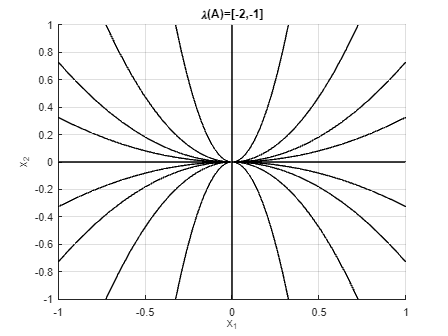

układ stabilny oscylacyjny tłumiony, para wartości własnych zespolonych sprzężonych,


M = 21

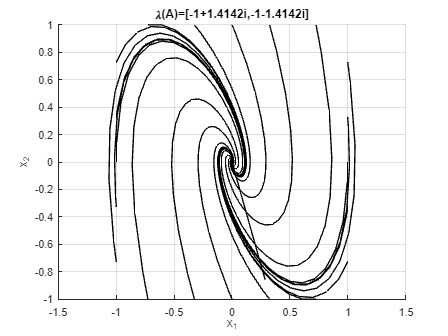

układ oscylacyjny nie tłumiony (granica stabilności), jedna para wartości własnych czysto urojonych,


M = 21

układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero,


M = 21

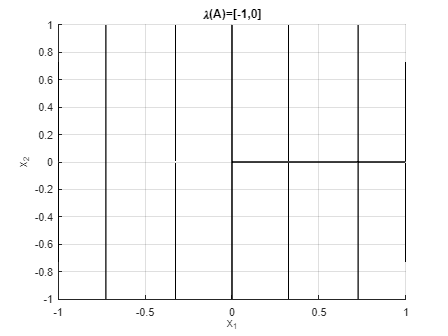

układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero,


M = 21

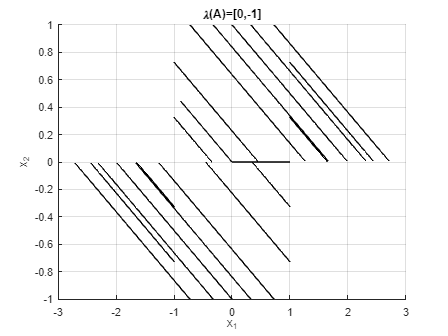

układ niestabilny, jedna wartość własna dodatnia, druga ujemna (punkt równowagi to punkt „siodłowy”),


M = 21

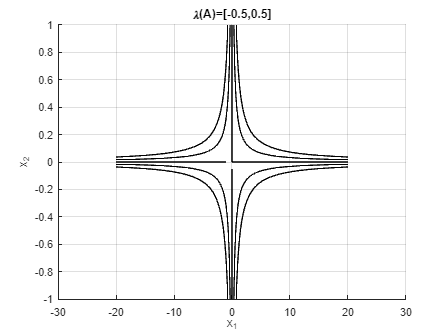

układ niestabilny, jedna wartość własna dodatnia, druga ujemna (punkt równowagi to punkt „siodłowy”),


M = 21

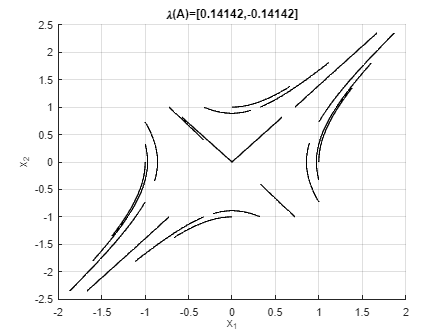

układ niestabilny, jedna wartość własna rzeczywista, druga równa zero,


M = 21

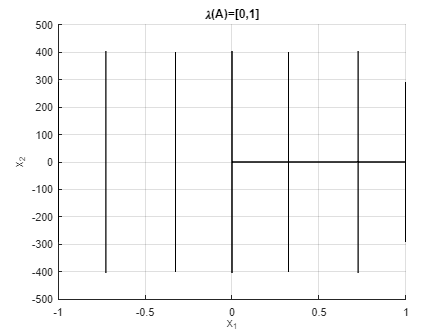


for i = 1:8
    disp(opis(i, :))
    A = cell2mat(Av(i, :, :));
    T=6; %czas końcowy
    [w J]=eig(A); %wektory i wartości własne
    figure;hold on; grid on;
    %Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
    %płaszczyzny fazowej:
    a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
    %cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
    X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
    for m=1:M
         x0=X2(:,m);
         x = sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
         x = x.x;
         plot(x(:,1),x(:,2),'k-', 'LineWidth', 0.5);
         plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
         title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
         xlabel('x_1');ylabel('x_2');
    end
end

## Wnioski

Podstawowe wnioski płynące z tego ćwiczenia z podstaw automatyki dotyczą analizy systemów dynamicznych drugiego rzędu z wykorzystaniem metody płaszczyzny fazowej. Oto kilka wniosków:

1. Metoda płaszczyzny fazowej jest przydatnym narzędziem do analizy własności systemów dynamicznych. Pozwala ona wizualnie przedstawić zachowanie systemu w przestrzeni fazowej, co ułatwia zrozumienie stabilności, oscylacji, tłumienia itp.

2. Trajektoria fazowa jest opisem ruchu systemu w przestrzeni fazowej, gdzie każda współrzędna reprezentuje stan systemu (np. położenie i prędkość). Analiza trajektorii pozwala ocenić stabilność systemu oraz identyfikować jego charakterystyczne zachowania.

3. Stabilność systemu można ocenić na podstawie układu trajektorii fazowych. Dla systemów stabilnych, trajektorie zbiegają się do punktu równowagi lub oscylują wokół niego. Dla systemów niestabilnych, trajektorie mogą oddalać się od punktu równowagi lub rosnąć nieograniczenie.

4. Dla systemów oscylacyjnych, tłumionych lub nie, trajektorie fazowe mogą opisywać oscylacje wokół punktu równowagi. Stopień tłumienia można ocenić na podstawie zmiany odległości między trajektoriami w kolejnych cyklach oscylacji.

5. Wartości własne macierzy stanu systemu mają istotny wpływ na zachowanie trajektorii fazowych. Rzeczywiste wartości własne odpowiadają oscylacjom lub zbieżności, podczas gdy wartości własne zespolone sprzężone mogą prowadzić do oscylacji tłumionych.

6. Metoda płaszczyzny fazowej umożliwia również analizę nieliniowych systemów dynamicznych, które mogą mieć bardziej skomplikowane trajektorie fazowe. Dzięki tej metodzie można identyfikować stabilne i niestabilne punkty równowagi oraz analizować zachowanie systemu wokół tych punktów.

Podsumowując, metoda płaszczyzny fazowej jest użytecznym narzędziem w analizie systemów dynamicznych drugiego rzędu. Pozwala ona na wizualizację i zrozumienie zachowania systemu, takich jak stabilność, oscylacje, tłumienie itp. Analiza trajektorii fazowych pozwala na ocenę i identyfikację charakterystycznych własności systemu.